# **A Live Script About Creating Live Scripts**

Code author: Dr. Matthew Stuber, [Stuber@alum.mit.edu](mailto:Stuber@alum.mit.edu)

This is a tutorial on how to create interactive notebooks for MATLAB, called Live Scripts.

_________________________________________________________________

## Learning Objectives

By the end of this notebook, you should be able to:

- Create a notebook from scratch with individual sections and appropriate organizational headings.

- Identify and distinguish the high-level primitives

- Format a problem statement with text, equations, and figures.

- Format and code a common subroutine.

- Use code cells for user interaction/input.

## Introduction

MATLAB Live Editor is a tool that lets you create interactive notebooks, called a MATLAB Live Script, that enables us to combine formatted text, computer code, interactive inputs and outputs, among other features, in a single publishable file. Live Scripts fall under a programming paradigm called [***Literate Programming***](https://en.wikipedia.org/wiki/Literate_programming) whereby a computer program or script is described/documented in a natural language (e.g., English) with formatted text and (interactive) code snippets.  

## Creating Notebooks

On the top toolbar, under the "Home" tab, instead of selecting "New Script" to open a blank .m file for conventional MATLAB programming, click "New Live Script" to open a blank .mlx file (i.e., a new Live Script) for literate programming. 

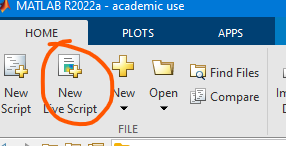

Once open, you should see the following helper pop-up with a link to learn more about MATLAB Live Editor and creating Live Scripts.

If the pop-up doesn't appear, the link is copied here to [Learn More](https://www.mathworks.com/products/matlab/live-editor.html) (click the link).

## View Options

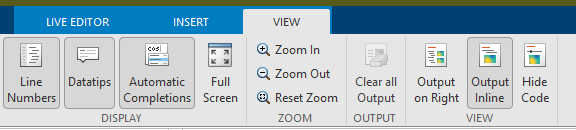

Under the VIEW tab, you have control over the how your Live Script displays and how you might interact with it. Specifically, the three options on the right control where the output is displayed (to the right of the Script or inline with the Script (like Jupyter notebooks). You also have the option to hide the code environments so that the Live Script appears as a standard text document. CAUTION: hiding the code should only really be done when you are using Live Scripts to create reports (print or PDF) and not when distributing to your students, as this option effectively removes (hides) both the interactive computing components. After you run a Live Script, any code output will remain as part of the document. All output can be cleared by clicking "Clear all Output". 

## Construction and Design

The formatting options are conveniently located under the LIVE EDITOR and INSERT tabs of the top toolbar.

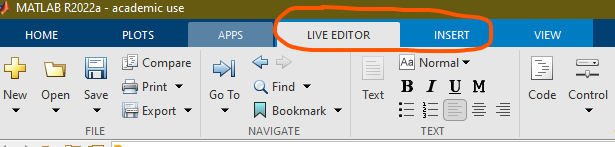

There are two main high-level primitives are text/markdown environments and code environments. As the names suggest, text/markdown environments allow you to write standard text, equations, and figures, whereas code environments allow you to write runable code. So far, this notebook has been using the text/markdown environment. We will introduce the code environment below.

### Code Environments

 A simple code environment looks like this:

x=3;
y=x^2;
z=sin(y);
fprintf("The answer is %6.4f.\n",z)

#### `!!! Interactive !!!`

Change the value of x in the above code and re-run the code to see how the answer changes.

Hint: run the previous code section by clicking the following button under the LIVE EDITOR tab:

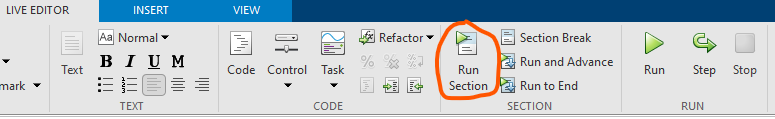

There are also creative ways to interact with code using the Control and Task options in the CODE section of the LIVE EDITOR tab.

One very important thing to note is that code environments like this are sequential in scope and behave like a script. This means that if you run each code section sequentially, each subsequent code environment will be "aware" of what happened in the previous blocks. Therefore, if you want to call a previously-calculated variable, you could do that:

z

If you want to have a common function that is callable anywhere in the Live Script, you need to create a function in a code environment at the very end of the Live Script. If you define a function anywhere other than the end, only code environments above it will be able to "see" it. Further, this would break how the Live Script is sectioned as it relegates the section with the function definition to be the final/end. Therefore, **only define functions at the end/bottom of the Live Script. **If you forget this rule, then you'll encounter the following error:

(Note that this is a non-interactive image of the error as errors prevent a Live Script from running)

At the end of this Live Script, there is a section called Common Functions where a function `testFun` has been defined (please review it). Therefore, the following code should run for you:

output=testFun(z)

#### `!!! Interactive !!!`

At the end of this Live Script in the Common Functions section, create a function called "goodFun" that calculates $y=\exp(x)$. Then, run the following code and verify the result:

output = goodFun(1)

#### `!!! Interactive !!!`

Create a subheading (Heading 2) below this line (in the blank space) for a subsection called, "Inserting Equations"

Typestting equations is integral to creating notes/handouts/problem statements throughout a chemical engineering curriculum. Consider a simple mixer (illustrated below) that combines two streams into a single stream:

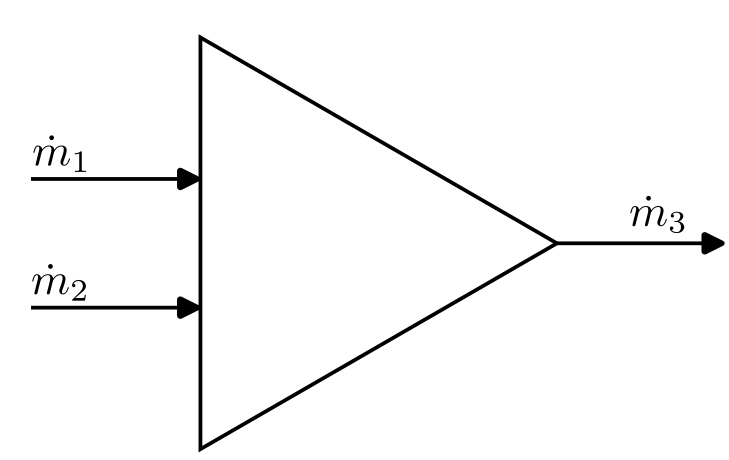

The overall mass balance on the mixer is given by the following equation:


$$\dot m_1+\dot m_2=\dot m_3.$$


There are two ways to input equations: using LaTeX and using the graphical interface. Under the INSERT tab of the toolbar, select "Equation" and then choose how you want to input an equation. If you know LaTeX, you can input equations rapidly and accurately via LaTeX source. If not, you should select the "Equation" option and use the graphical interface. Both are illustrated below.

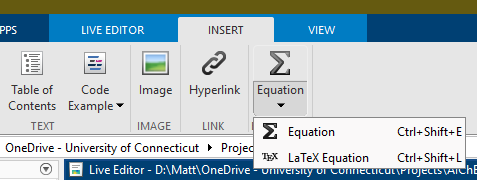

#### Graphical Equation Editor

If you go this route, a new EQUATION tab will appear in the main toolbar that gives you a point-and-click interface for inputting equations. If you hover your mouse over the symbols, you will see the corresponding LaTeX source code.

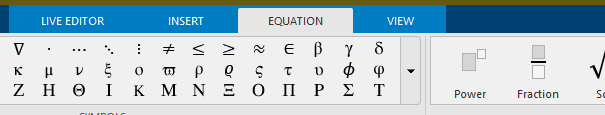

Typing "m_1+m_2=m_3" will yield the following result:


$$m_1 +m_2 =m_3$$


Then, clicking the expand arrow on the "Structures" menu will bring up accent characters. If you select each "m" individually, and then click the "dot" accent, this will add the overdot.

#### `!!! Interactive !!!`

Create the correct mass balance equation for the mixer, complete with the overdot accents.

#### LaTeX Editor

If you're proficient with LaTeX, this should be how equations are typeset. On the INSERT tab, click the expand arrow on Equation and select LaTeX Equation (ctrl+shift+L hotkey). The following interface will open for you to type LaTeX source:

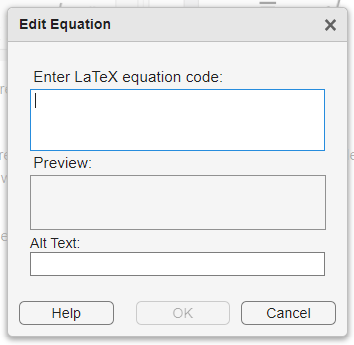

#### `!!! Optional Interactive !!!`

Create the correct mass balance equation for the mixer, complete with the overdot accents, using LaTeX.

## Continue Learning

There are many other features/functionalities of the Live Editor that were not covered in this brief tutorial. You will find online resources that cover these. However, what was covered here should provide you with everything you need to create and deploy Live Scripts in your chemical engineering courses. 

## Common Functions

function o = testFun(in)
o = in^3;
end

### `!!! Interactive !!!`

Create your common function here.